# Plotting Roberto's Exp. Data

## Loading data

% CN0 data
load 'CN0_joint.mat';
% Elevation angle data
load 'EL_joint.mat';
% Pesudorange error data
load 'res_joint.mat';

data_t = 0.2*(1:length(res_joint));

## Plotting data for each PRN

There are some NaNs in 'res_joint' and some zeros in 'CN0_joint'. You need to remove those data before processing.

## Time history

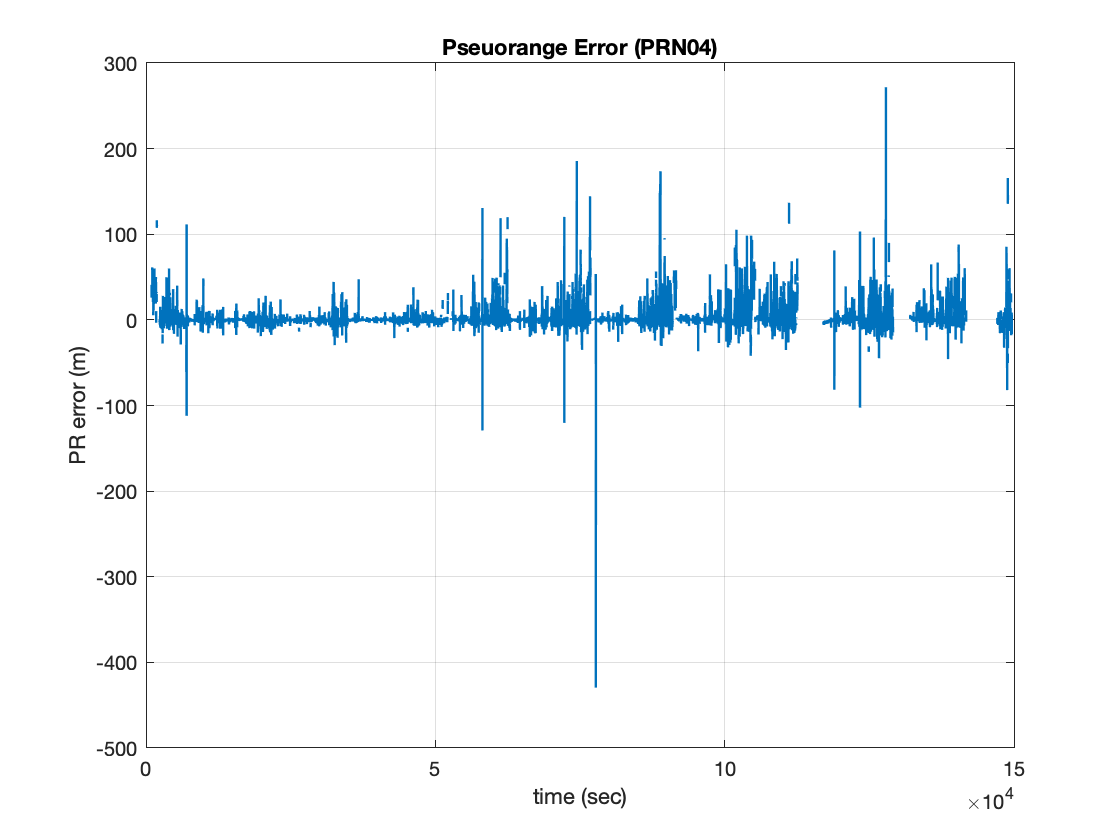

figure_PRN =4;

temp_data_CN0 = CN0_joint(figure_PRN,:);
temp_data_res = res_joint(figure_PRN,:);

index_data = temp_data_res == 0 | isnan(temp_data_res);

data_pre = res_joint(figure_PRN,:); data_pre(index_data) = NaN;
data_el = EL_joint(figure_PRN,:); data_el(index_data) = NaN;
data_cn0 = CN0_joint(figure_PRN,:); data_cn0(index_data) = NaN;

clf;
plot(data_t,data_pre); grid on;
xlabel('time (sec)'); ylabel('PR error (m)'); title(sprintf('Pseuorange Error (PRN%02d)',figure_PRN));

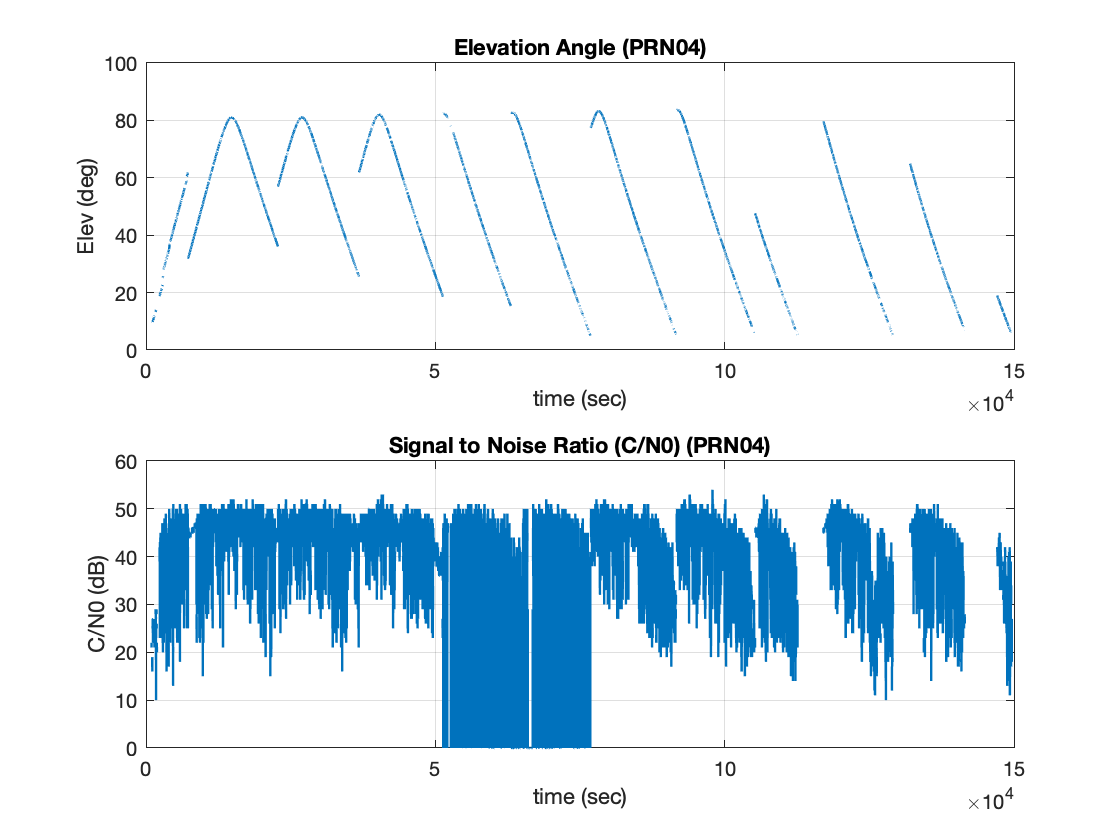


clf;
subplot(211);
plot(data_t,data_el/pi*180); grid on;
xlabel('time (sec)'); ylabel('Elev (deg)'); title(sprintf('Elevation Angle (PRN%02d)',figure_PRN));
subplot(212);
plot(data_t,data_cn0); grid on;
xlabel('time (sec)'); ylabel('C/N0 (dB)'); title(sprintf('Signal to Noise Ratio (C/N0) (PRN%02d)',figure_PRN));

## Distribution

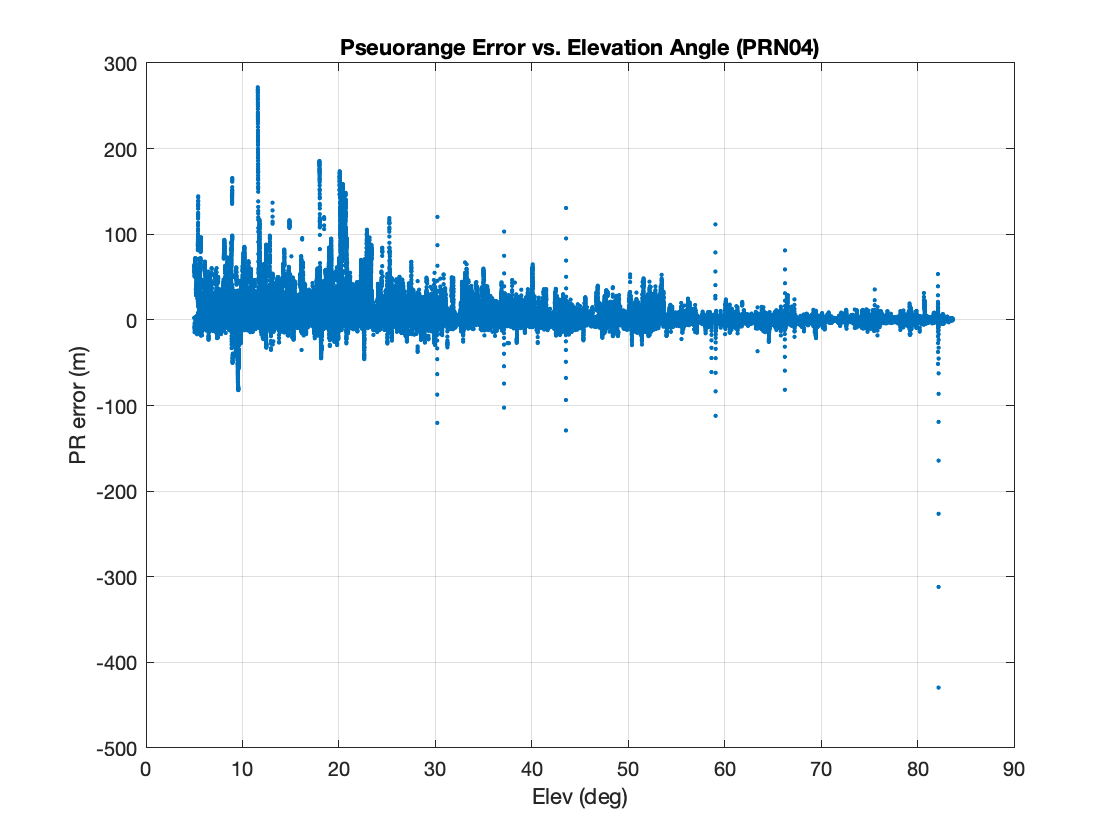

clf;
plot(data_el/pi*180,data_pre,'.'); grid on;
xlabel('Elev (deg)'); ylabel('PR error (m)'); title(sprintf('Pseuorange Error vs. Elevation Angle (PRN%02d)',figure_PRN));

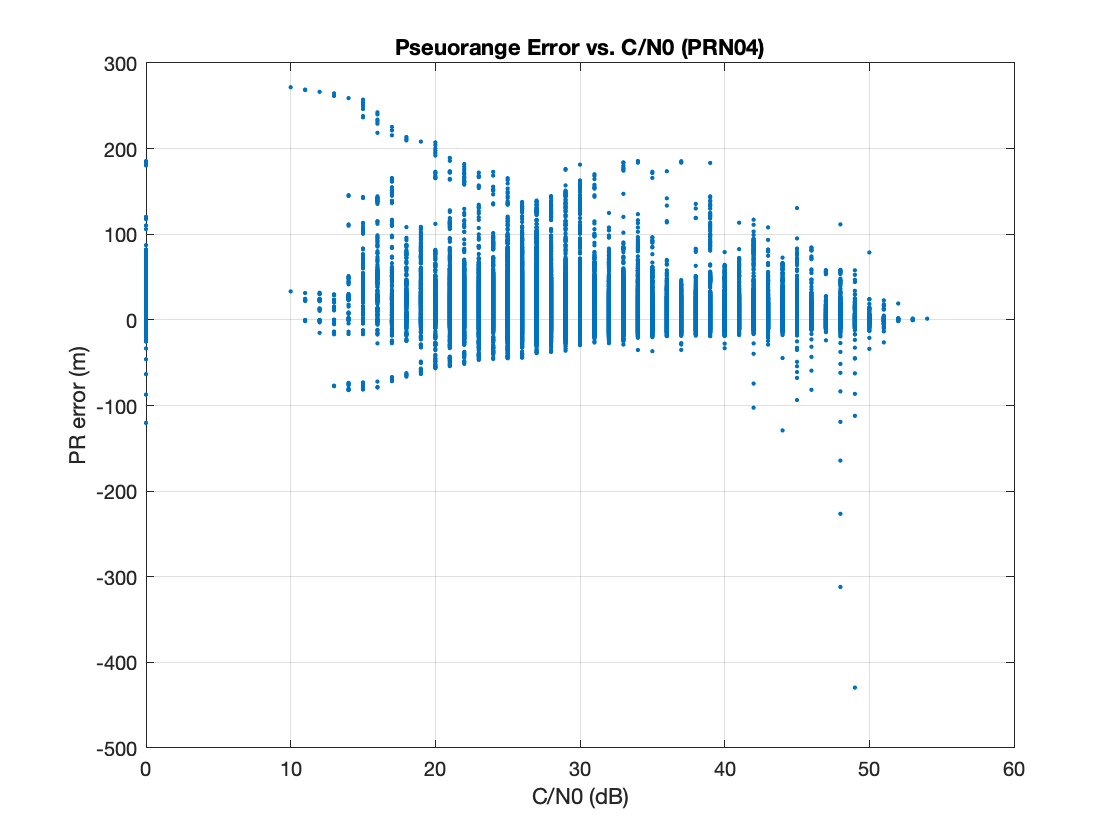


clf;
plot(data_cn0,data_pre,'.'); grid on;
xlabel('C/N0 (dB)'); ylabel('PR error (m)'); title(sprintf('Pseuorange Error vs. C/N0 (PRN%02d)',figure_PRN));

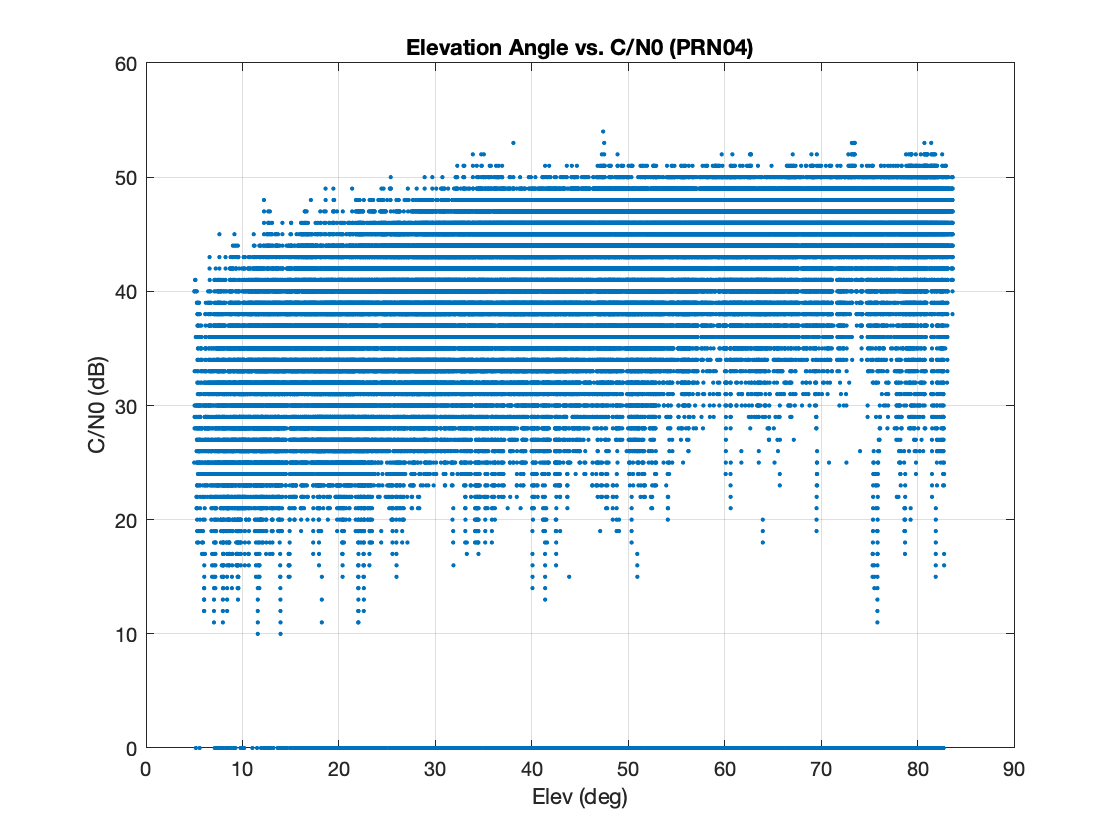

clf;
plot(data_el/pi*180,data_cn0,'.'); grid on;
xlabel('Elev (deg)'); ylabel('C/N0 (dB)'); title(sprintf('Elevation Angle vs. C/N0 (PRN%02d)',figure_PRN));

## Plotting data for all PRN

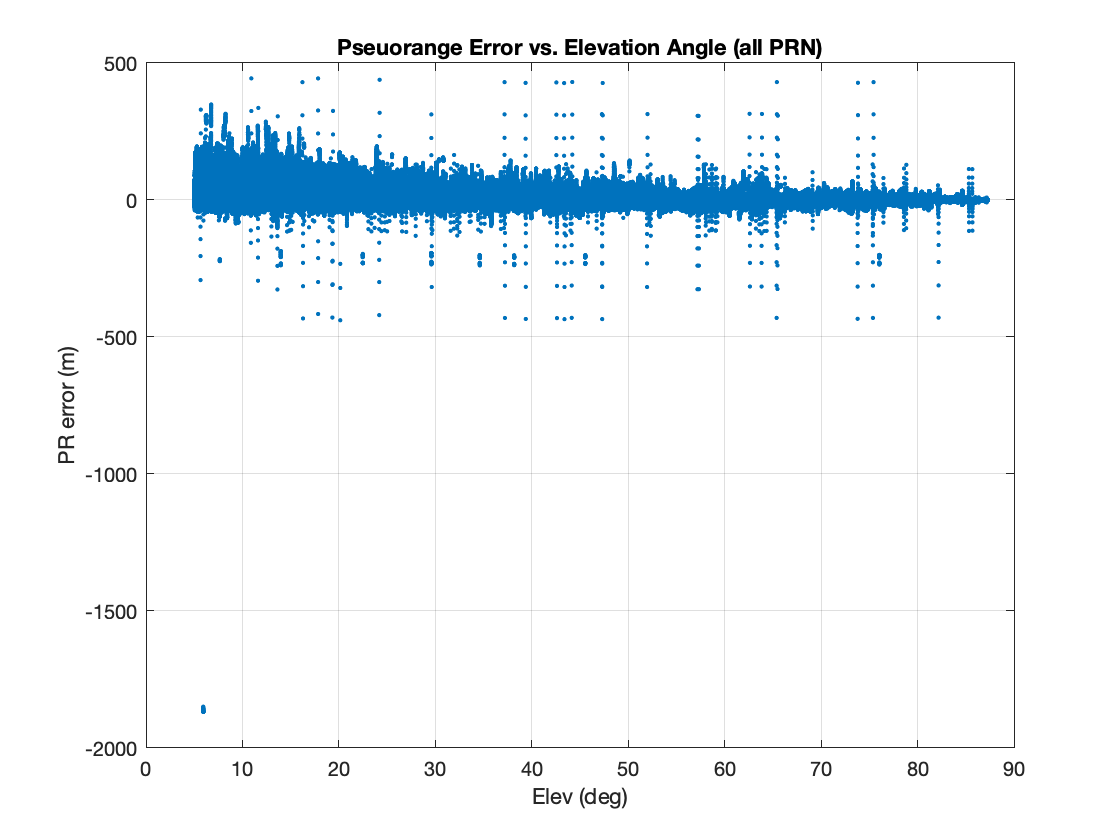

index_data = CN0_joint == 0 | isnan(res_joint);
data_temp = res_joint; data_temp(index_data) = NaN;
alldata_pre = data_temp(:);
data_temp = EL_joint; data_temp(index_data) = NaN;
alldata_el = data_temp(:);
data_temp = CN0_joint; data_temp(index_data) = NaN;
alldata_cn0 = data_temp(:);

clf;
plot(alldata_el/pi*180,alldata_pre,'.'); grid on;
xlabel('Elev (deg)'); ylabel('PR error (m)'); title('Pseuorange Error vs. Elevation Angle (all PRN)');

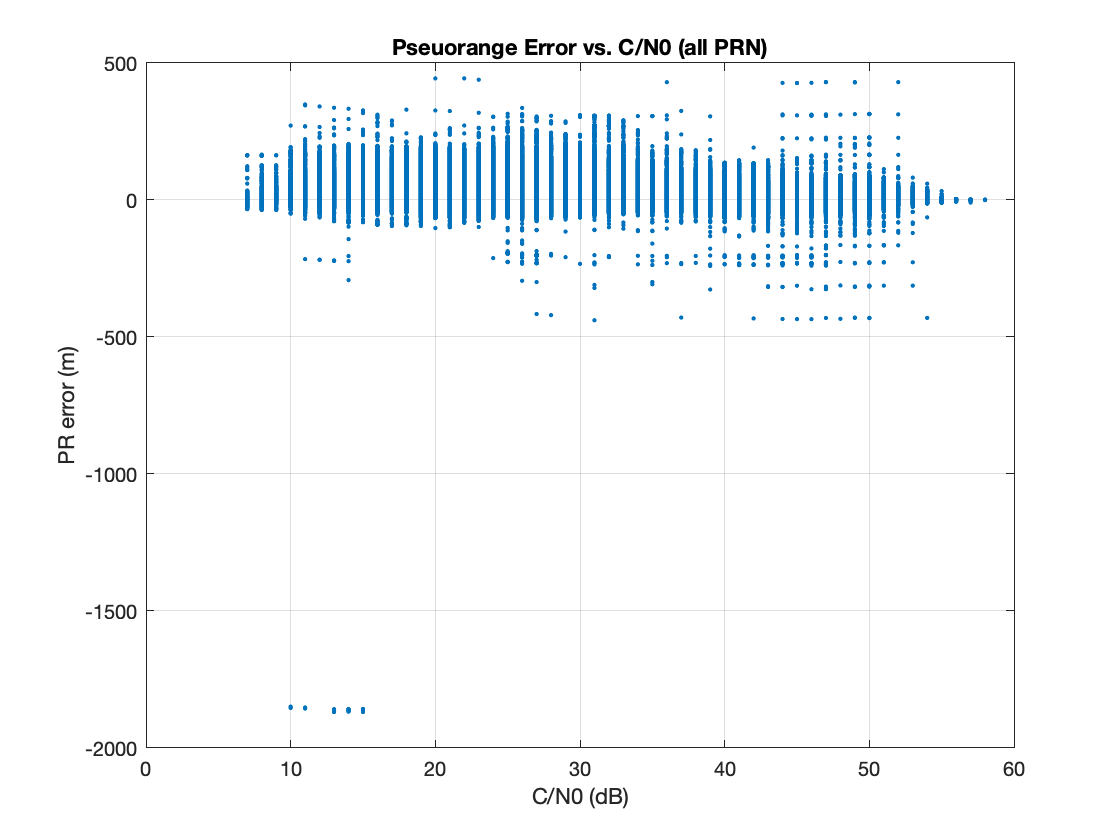


clf;
plot(alldata_cn0,alldata_pre,'.'); grid on;
xlabel('C/N0 (dB)'); ylabel('PR error (m)'); title('Pseuorange Error vs. C/N0 (all PRN)');

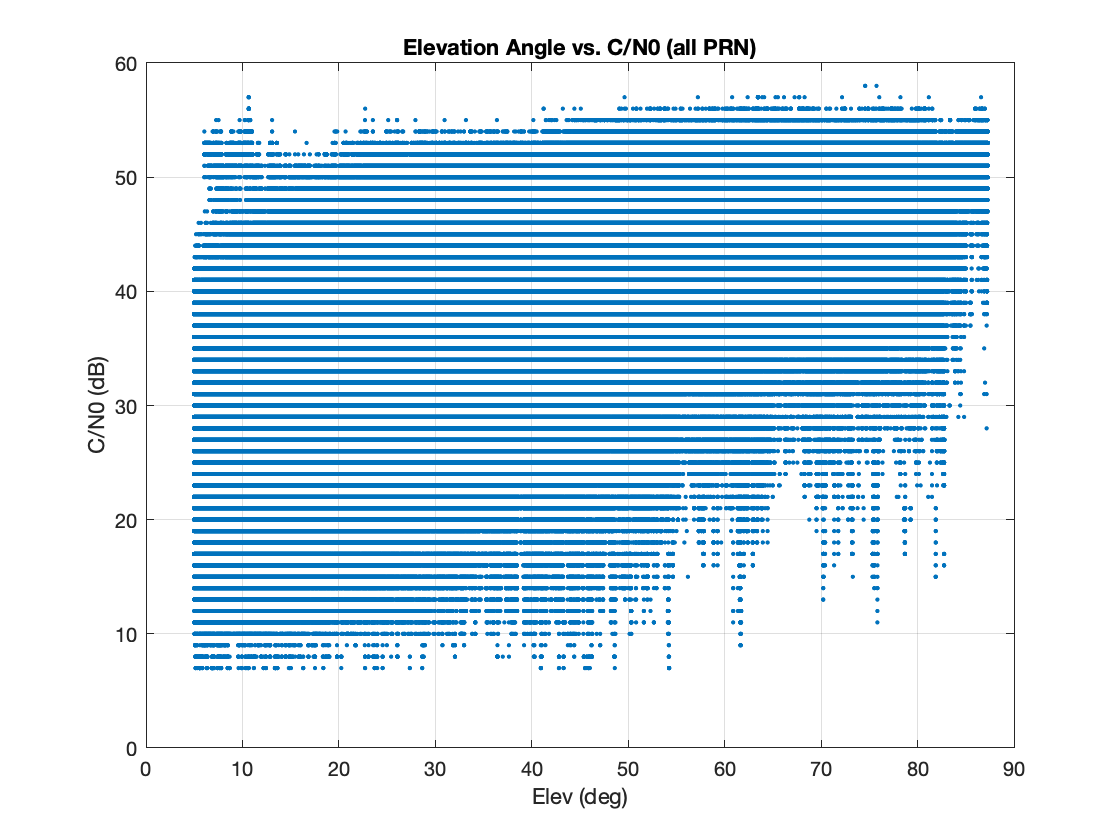


clf;
plot(alldata_el/pi*180,alldata_cn0,'.'); grid on;
xlabel('Elev (deg)'); ylabel('C/N0 (dB)'); title('Elevation Angle vs. C/N0 (all PRN)');